nums = [20:1:30];
acctrains = [];   %zeros(1,length(nums))
acctests = [];

tic
for i = nums
    
    group = string(y_nir_total);
    data = X_nir_norm;
    label = group(1:600);

    [vsel_spa] = feature_spa(data(training(cvp), :), 624, i)    

    train_data  = data(training(cvp), vsel_spa);
    train_label = label(training(cvp));
    test_data   = data(test(cvp), vsel_spa);
    test_label  = label(test(cvp));

    rng(1); % For reproducibility
    randIndex1 = randperm(size(train_data,1));
    rng(1); % For reproducibility
    randIndex2 = randperm(size(test_data,1));

    train_data  = train_data(randIndex1, :);
    train_label = train_label(randIndex1);
    test_data   = test_data(randIndex2, :);
    test_label  = test_label(randIndex2);

    rng(1); % For reproducibility
    Mdl = TreeBagger(100, train_data, train_label, 'OOBPrediction', 'On', 'Method', 'classification')

    % view(Mdl.Trees{1},'Mode','graph')
    % figure;
    % oobErrorBaggedEnsemble = oobError(Mdl);
    % plot(oobErrorBaggedEnsemble)
    % xlabel 'Number of grown trees';
    % ylabel 'Out-of-bag classification error';

    simy1 = predict(Mdl, train_data);
    simy2 = predict(Mdl, test_data);

    s1 = length(simy1) ;
    hitNum1 = 0 ;
    for k = 1:s1
        if( simy1(k) == train_label(k))
            hitNum1 = hitNum1 + 1 ;
        end
    end
    sprintf('识别率是 %3.3f%%', 100 * hitNum1 / s1 )

    s2 = length(simy2) ;
    hitNum2 = 0 ;
    for j = 1:s2
        if( simy2(j) == test_label(j))
            hitNum2 = hitNum2 + 1 ;
        end
    end
    sprintf('识别率是 %3.3f%%', 100 * hitNum2 / s2 )
    
    acctrains = [acctrains, 100 * hitNum1 / s1];
    acctests = [acctests, 100 * hitNum2 / s2];    

end

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x20]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   20
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 76.667%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x21]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   21
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 76.667%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x22]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   22
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 75.000%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x23]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   23
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 78.333%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x24]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   24
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 76.111%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285   271


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x25]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   25
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 77.222%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285   271   279


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x26]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   26
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 77.222%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285   271   279   272


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x27]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   27
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 76.667%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285   271   279   272   278


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x28]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   28
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 76.667%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285   271   279   272   278   277


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x29]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   29
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 77.222%'

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280   285   271   279   272   278   277   273


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x30]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   30
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 78.889%'

acctrains

acctrains =    100   100   100   100   100   100   100   100   100   100   100


acctests

acctests =        76.667       76.667           75       78.333       76.111       77.222       77.222       76.667       76.667       77.222       78.889


nums

nums =     20    21    22    23    24    25    26    27    28    29    30


vsel_spa = feature_spa(data(training(cvp), :), 624, 23)

vsel_spa =    624   260   259   261   258   262   257   263   264   256   265   255   266   267   268   254   283   269   282   284   270   281   280



group = string(y_nir_total);
data = X_nir_norm;
label = group(1:600);
 
    
train_data  = data(training(cvp), vsel_spa);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_spa);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

valid_data = X_mixnir_norm(:,vsel_spa);
valid_label = group(601:end);

rng(1); % For reproducibility
Mdl = TreeBagger(100, train_data, train_label, 'OOBPrediction', 'On', 'Method', 'classification')

Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x23]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   23
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


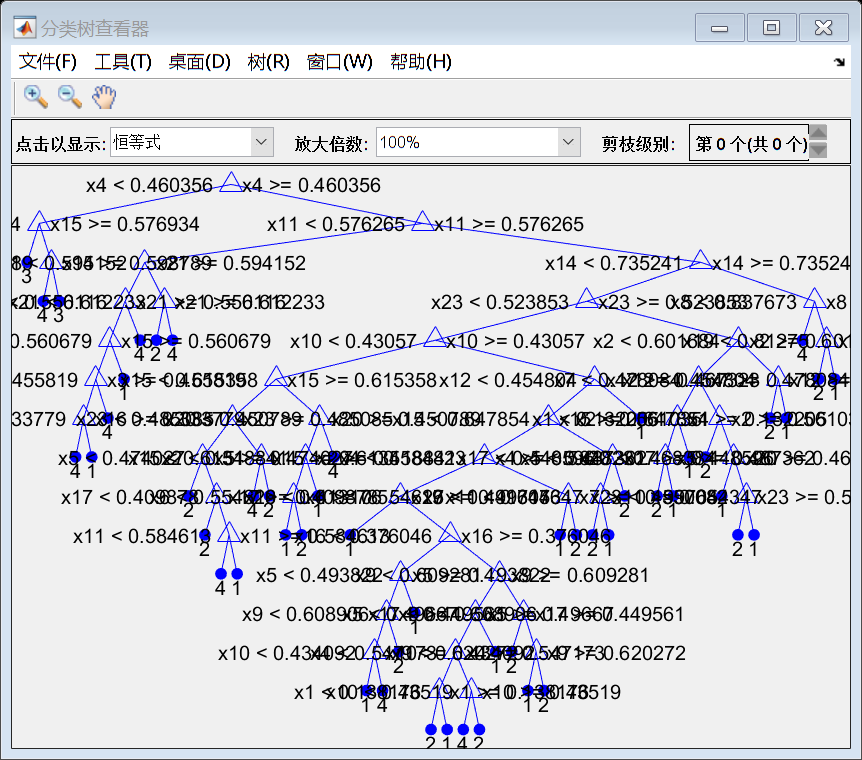


view(Mdl.Trees{1},'Mode','graph')

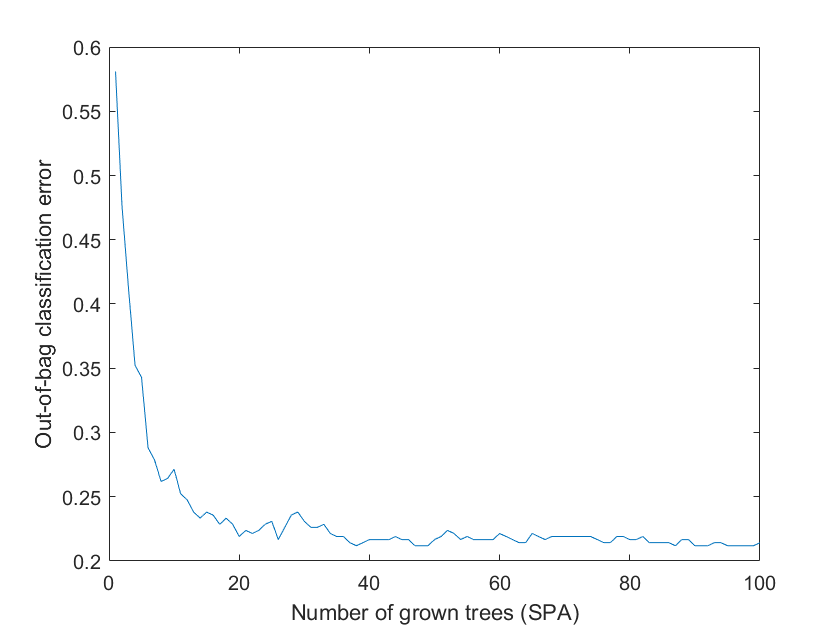

figure;
oobErrorBaggedEnsemble_spa = oobError(Mdl);
plot(oobErrorBaggedEnsemble_spa)
xlabel 'Number of grown trees (SPA)';
ylabel 'Out-of-bag classification error';


simy1 = predict(Mdl, train_data);
simy2 = predict(Mdl, test_data);
simy3 = predict(Mdl, valid_data);

s1 = length(simy1) ;
hitNum1 = 0 ;
for k = 1:s1
    if( simy1(k) == train_label(k))
        hitNum1 = hitNum1 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum1 / s1 )

ans = '识别率是 100.000%'


s2 = length(simy2) ;
hitNum2 = 0 ;
for j = 1:s2
    if( simy2(j) == test_label(j))
        hitNum2 = hitNum2 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum2 / s2 )

ans = '识别率是 78.333%'


s3 = length(simy3) ;
hitNum3 = 0 ;
for j = 1:s3
    if( simy3(j) == valid_label(j))
       hitNum3 = hitNum3 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum3 / s3 )

ans = '识别率是 20.000%'